sensetivityon1=readtable('sensetivity_on1.csv');

sensetivityon1.Var49(1,1) = 100;
sensetivityon1.Properties.VariableNames(49) = "o_Op1_Jrms";

Turn=sensetivityon1.o_Turn_Coil ;
o_op1_ipk=sensetivityon1.o_Op1_ipk;
p_parallel_path=4;
copper_area=sensetivityon1.o_Op1_copper_area;
init_Turn=11;
sensetivityon1.o_Op1_Jrms=o_op1_ipk./sqrt(2).*Turn/p_parallel_path./copper_area.*Turn/init_Turn;

figure1 = figure('WindowState','maximized','Name','Figure','Color',[1 1 1]);
subplot1=subplot(2,1,1,"parent",figure1)

subplot1 =   Axes - 속성 있음:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.5838 0.7750 0.3412]
            Units: 'normalized'

  모든 속성 표시


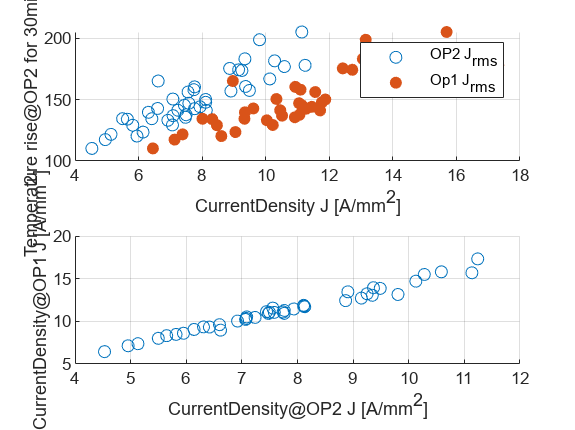

scatter(sensetivityon1.o_Op2_Jrms,sensetivityon1.o_Op2_max_temp,'DisplayName','OP2 J_{rms}')
hold on
grid on
scatter(sensetivityon1.o_Op1_Jrms,sensetivityon1.o_Op2_max_temp,'filled','DisplayName','Op1 J_{rms}')
xlabel('CurrentDensity J [A/mm^{2}]');
ylabel('Temperature rise@OP2 for 30min[degC]');
legend

subplot2 = subplot(2,1,2,'Parent',figure1);
scatter(sensetivityon1.o_Op2_Jrms,sensetivityon1.o_Op1_Jrms);
xlabel('CurrentDensity@OP2 J [A/mm^{2}]');
ylabel('CurrentDensity@OP1 J [A/mm^{2}]');
grid on